# Add Slides to a Presentation

Import the PPT package so that you do not have to use long, fully qualified names for the PPT API classes.

import mlreportgen.ppt.*


Create and open a presentation named `myPresentation.pptx`.

ppt = Presentation('myPresentation.pptx');
open(ppt);

Add the first slide and specify the slide layout, but not the slide master or location.

contentSlide = add(ppt,'Title and Content');
replace(contentSlide,'Title','This is the Title of the Slide Content');

Add another slide using the `Office Theme` slide master. Insert it before the slide represented by `contentSlide`.

titleSlide = add(ppt,'Title Slide','Office Theme',contentSlide);
replace(titleSlide,'Title','Presentation Title');

Add a blank slide using the `Office Theme` slide master. Make the new slide the second slide in the presentation.

blankSlide = add(ppt,'Blank','Office Theme',2);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the  generated presentation:

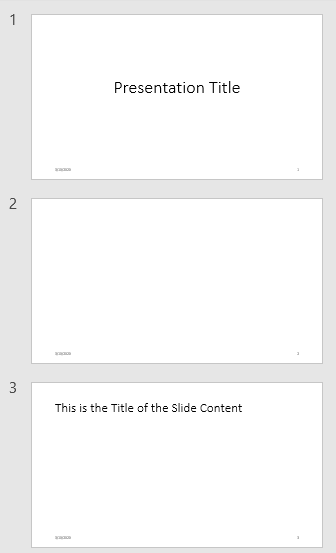

*Copyright 2020 The MathWorks, Inc.*